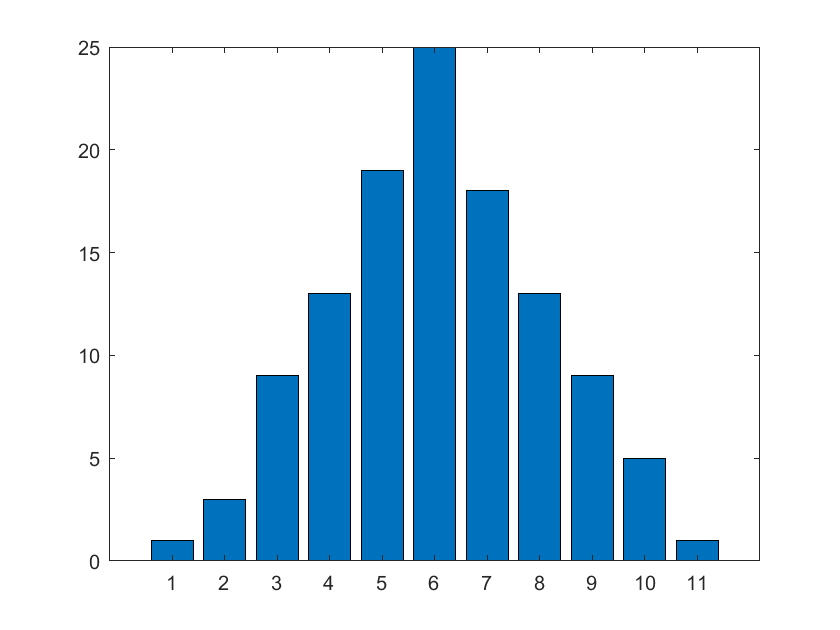

clear
f=[1 3 9 13 19 25 18 13 9 5 1];
bar(f)

n=sum(f);
r0=0.6;
x=0.65:0.1:1.65;
xba=sum(f.*x)/sum(f);% 算数均数
a{1}=xba;
f1(1)=0;
for i=1:length(f)-1
    f1(i+1)=f1(i)+f(i);
end
% f1(12)=inf;
% for i=1:n
%     for j=1:11
%         if i>f1(j) && i<=f1(j+1)
%             d(i)=x(j);
%         end
%     end
% end
% s=std(d);% 标准差

s=sqrt((sum(f.*x.^2)-(sum(f.*x)^2/n))/(n-1))

s = 0.2044

a{2}=s;
u=1.64;
a{3}=[xba-u*s xba+u*s];
a{4}=[f1((0.8-0.6)/sym(0.1)+1) f1((1.5-0.6)/sym(0.1)+1)]/n

索引超出数组元素的数目(1)。